# Testing how sensitive reflectance is to geometry

By Andrew John Buggee

folderName = ['/Users/andrewbuggee/Documents/CU-Boulder-ATOC/',...
    'Hyperspectral-Cloud-Droplet-Retrieval/LibRadTran/libRadtran-2.0.4/MODIS_day_194_year_2021_time_1935/'];


inputName = {'test1.INP','test2.INP', 'test3.INP', 'test4.INP', 'test5.INP', 'test6.INP', 'test7.INP'};

outputName = {'test1', 'test2', 'test3', 'test4', 'test5', 'test6', 'test7'};


for nn = 1:length(inputName)
    % Solve the equation of radiative transfer
    [inputSettings] = runUVSPEC(folderName,inputName{nn},outputName{nn});


    % extract the output


    [ds,irrad_HU,~] = readUVSPEC(folderName,outputName{nn},inputSettings(2,:));

    
    % Compute the reflectance
    [R(nn), ~] = reflectanceFunction(inputSettings(2,:),ds);
    
end



## Plot the Results for Changing Surface Albedo

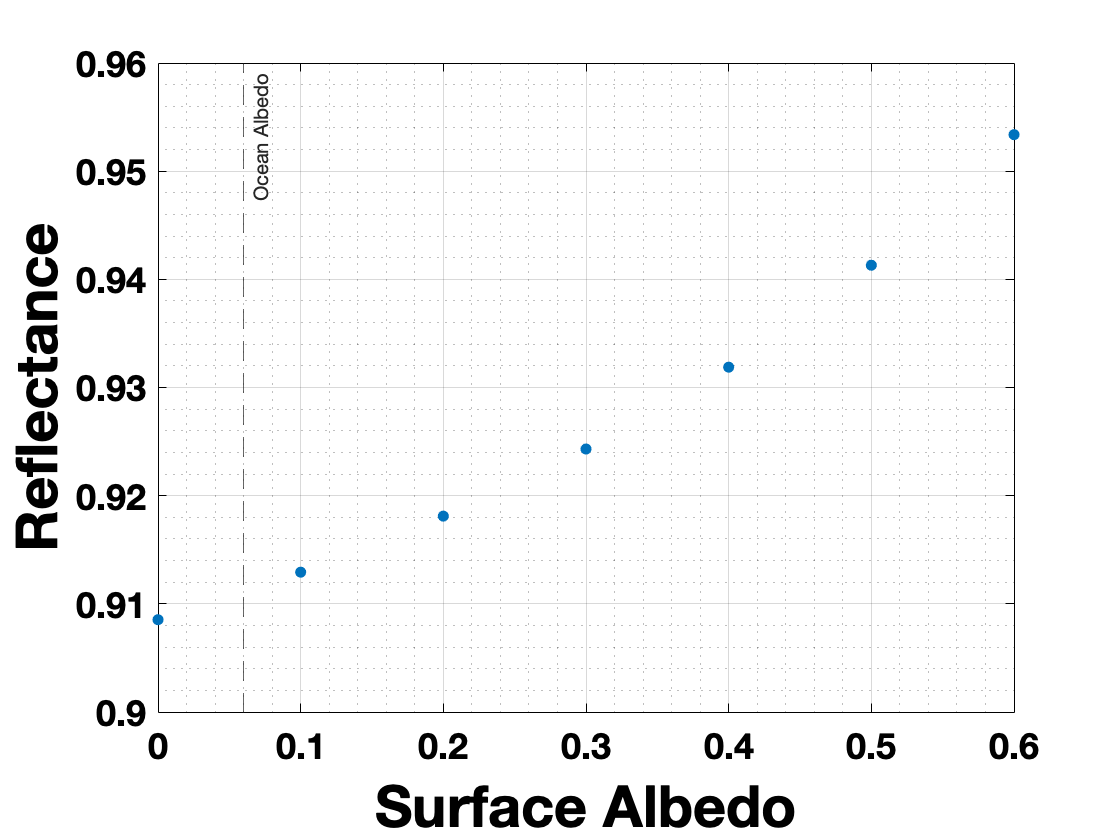

% Define whats changing
alb = 0:0.1:0.6;
figure; plot(alb, R, '.')
hold on
xline(0.06,'--','Ocean Albedo')
xlabel('Surface Albedo')
ylabel('Reflectance')
grid on; grid minor

## Plot the Results for Changing Cloud cover

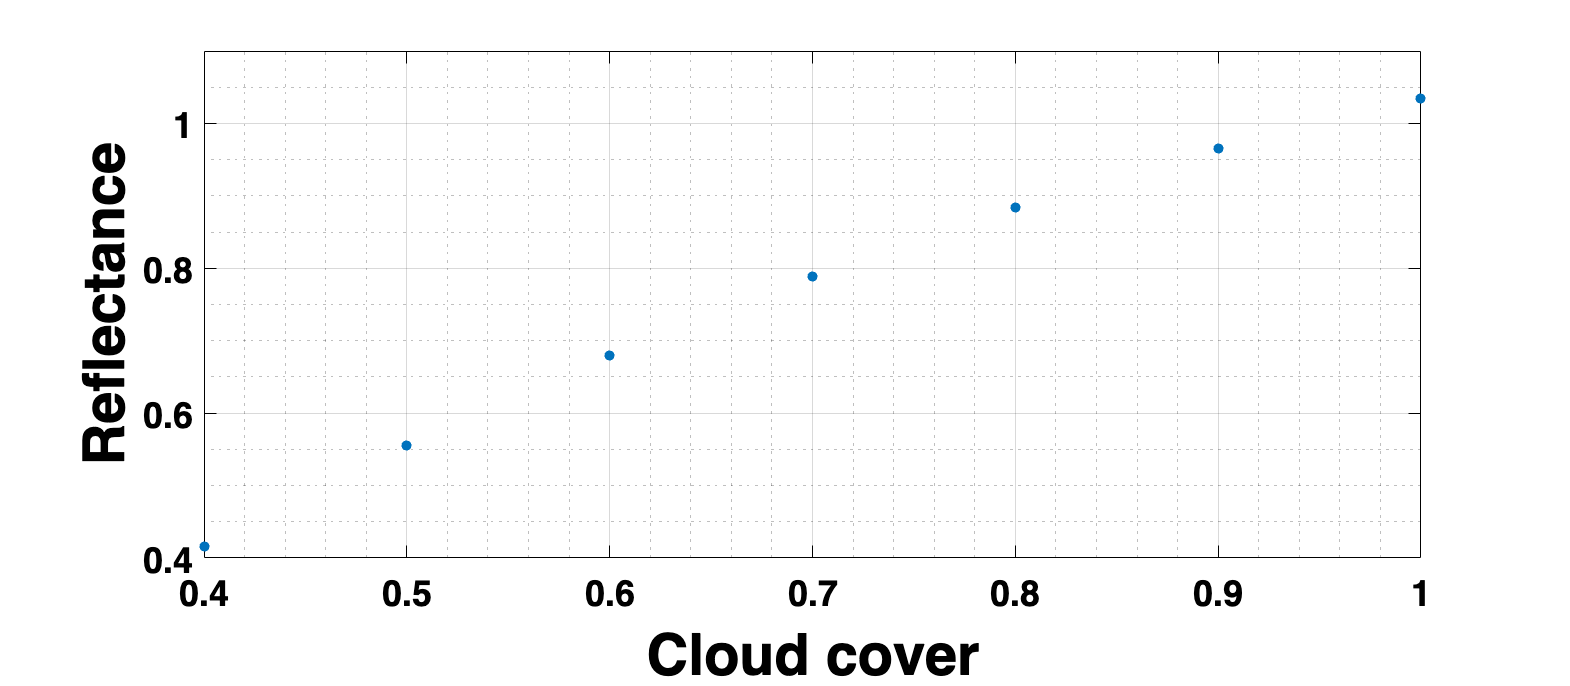

% Define whats changing
cloudCover = 0.4:0.1:1;
f = figure; plot(cloudCover, R, '.')
hold on
xlabel('Cloud cover')
ylabel('Reflectance')
grid on; grid minor
set(f,'position',[0 0 800, 350])

#### Reflectance appears to changes linearly with cloud cover. We can expect reflectance to decrease sharply if we lower the amount of cloud cover in our libRadTran files.